clear; clc;
warning off;

# Exercise 3.7

Derive the equations of motion using the Lagrange’s method for the 2-link manipulator shown in the figure below, with the end-effector constrained to move along a line.

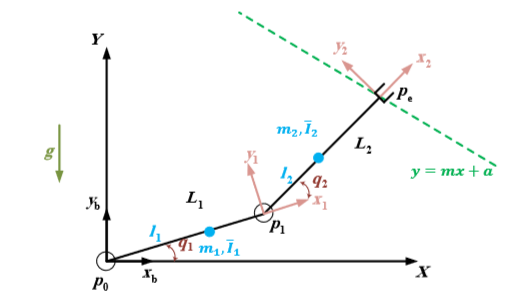

## Numerical values:

L1 = 1;
L2 = 1;
l1 = L1/2;
l2 = L2/2;
ml1 = 50;
ml2 = 50;

Il1z = 10;
Il2z = 10;
mm1 = 0;
mm2 = 0;
Im1 = 0;
Im2 = 0;

I1 = diag([0,0,Il1z]);
I2 = diag([0,0,Il2z]);

g = 9.8;
g0 = [0; -g; 0];

b_f = 10;

% constraint parameters
m = -1;
a = 1.5;

% initial condition that satisfies the constraint
q10 = 1.44124;
q20 = -1.95519;
q0 = [q10; q20];
q0dot = [0; 0];

Ts = 1e-2;

## Symbolic variables:

syms lambda real % Lagrange multiplier

q = sym('q', [2,1]);
dq = sym('dq', [2,1]);
ddq = sym('ddq', [2,1]);
tau = sym('tau', [2,1]);

## Transformation matrices:

T=@(a,al,d,th)([cos(th), -sin(th)*cos(al), sin(th)*sin(al), a*cos(th); sin(th), cos(th)*cos(al), -cos(th)*sin(al), a*sin(th); 0, sin(al), cos(al), d; 0, 0, 0, 1]);

A1_0 = T( L1 , 0 , 0 , q(1) );
A2_1 = T( L2 , 0 , 0 , q(2) );

T1_0 = A1_0;
T2_0 = A1_0 * A2_1;

R1_0 = T1_0(1:3,1:3);
R2_0 = T2_0(1:3,1:3);

## Jacobian for each center of mass:

Z0 = [0;0;1];
Z1 = T1_0(1:3,3);
Z2 = T2_0(1:3,3);

P0 = [0;0;0];
P1 = T1_0(1:3,4);
P2 = T2_0(1:3,4);

Pl1 = P0 + R1_0*[l1;0;0];
Pl2 = P1 + R2_0*[l2;0;0];

Jl1 = [cross(Z0,(Pl1-P0)),zeros(3,1); Z0,zeros(3,1)];
Jl2 = [cross(Z0,(Pl2-P0)),cross(Z1,(Pl2-P1)); Z0,Z1];

## Kinetic and Potential Energy:

KineticEnergy = 1/2*dq.'*(Jl1(1:3,:).'*ml1*Jl1(1:3,:) + Jl2(1:3,:).'*ml2*Jl2(1:3,:))*dq +1/2*dq.'*(Jl1(4:6,:).'*R1_0*I1*R1_0.'*Jl1(4:6,:) + Jl2(4:6,:).'*R2_0*I2*R2_0.'*Jl2(4:6,:))*dq;

PotentialEnergy = - ml1 * g0.' * Pl1 - ml2 * g0.' * Pl2;

## Constraint:

The manipulator is constrained to move along a line:

$y_e = m x_e + a$, where the end-effector position is described by: $P_e = \left[ x_e \ , y_e \ , \ 0 \right]^T$

The constraint can therefore be expressed with respect to the joint positions through direct kinematics:


$$ \phi(q_1 , q_2)   =   L_1 s_1 + L_2 s_{12} - m (L_1 c_1 + L_2 c_{12}) - a$$


From this, we compute the constraint Jacobian:


$$J_\phi(q)
=
\left[\matrix{
\frac{\partial \phi}{\partial q_1} & 
 \frac{\partial \phi}{\partial q_2}
}\right]
 =
\left[\matrix{
        L_1 c_1 + L_2 c_{12} + m (L_1 s_1 + L_2 s_{12}) & 
        L_2 c_{12} + m L_2 s_{12}
        }\right]$$


constraint = L1*sin(q(1)) + L2*sin(q(1)+q(2)) - m*(L1*cos(q(1))+L2*cos(q(1)+q(2))) - a;

dConstraint_q  = jacobian(constraint,q);
ddConstraint_q = jacobian(dConstraint_q*dq,q);

## Dynamic model with constraint:


$$B(q)\ddot{q} + C(q, \dot{q} )\dot{q} + g(q) + J_\phi^T (q)\lambda= \tau $$


% Lagrangian
Lagrangian = KineticEnergy - PotentialEnergy - lambda*constraint;
%simplify(Lagrangian)

dLag_dq  = jacobian(Lagrangian, dq).';
dLag_q   = jacobian(Lagrangian, q).';
ddLag_dq = jacobian(dLag_dq, dq);
ddLag_q  = jacobian(dLag_dq, q);

inertiaMatrix = ddLag_dq; % B
gVector = jacobian(PotentialEnergy,q).'; % g
coriolisMatrix = ddLag_q*dq - jacobian(KineticEnergy,q).'; % C
frictionOnJoints = -b_f*dq; % F

% Check if correct (should be zero):
simplify(dLag_q + lambda*dConstraint_q.' + gVector - jacobian(KineticEnergy,q).')

$$ans = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

## Closed-form solution to Lagrange multipliers:


$$\left[ \matrix{ B(q)  & J_\phi^T(q) \cr
             J_\phi(q) & 0} \right]
\left[ \matrix{ \ddot{q} \cr 
\lambda } \right]
=
\left[ \matrix{\tau - n(q,\dot{q}) \cr
 -\dot{J}_\phi(q) \dot{q} }\right]$$


where $n (q,\dot{q}) = C(q,\dot{q})\dot{q}+g(q)$

modifiedInertiaMatrix = [inertiaMatrix dConstraint_q.';
                         dConstraint_q              0];      

RHS_withoutConstraint = tau - (coriolisMatrix + gVector - frictionOnJoints);
%simplify(RHS_withoutConstraint)  

RHS = [RHS_withoutConstraint;
      -ddConstraint_q*dq];
%simplify(RHS)


% Create functions used in simulation
matlabFunction(modifiedInertiaMatrix,'File','modifiedInertiaMatrix','Vars',{q});
matlabFunction(RHS,'File','RHS','Vars',{q,dq,tau});

matlabFunction(inertiaMatrix,'File','inertiaMatrix','Vars',{q});
matlabFunction(RHS_withoutConstraint,'File','RHS_withoutConstraint','Vars',{q,dq,tau});

## Simulation without constraint:

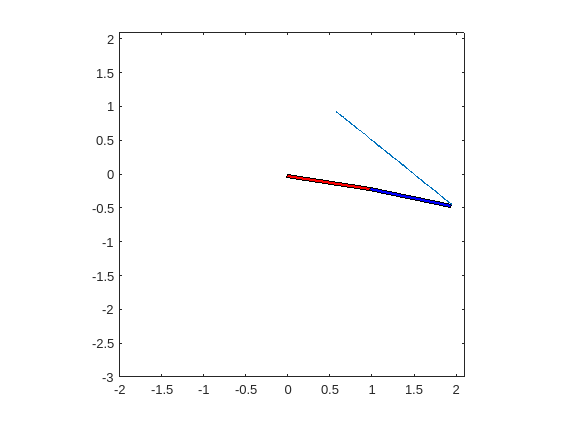

sim('line_sim_withoutConstraint')
pause(1);
visualization_2link

## Simulation with constraint:

clf;
sim('line_sim')
pause(1);
visualization_2link